clear
clc
set(0,'defaulttextinterpreter','latex')

% Load RSSI data from the file
rssiData = dlmread('RSSI_tp_node_1.txt', '\t'); %#ok<*DLMRD>

% Distance array
d = [0:0.05:1, 1.2:0.2:5];

% Extract raw and filtered measurements
rawMeasurements = rssiData(1:2:end);
filteredMeasurements = rssiData(2:2:end);

% Number of measurements per distance value
numMeasurements = 50;

% Initialize arrays for means, standard deviations, and confidence intervals
rawMeans = zeros(length(d), 1);
filteredMeans = zeros(length(d), 1);
rawCI = zeros(length(d), 2);
filteredCI = zeros(length(d), 2);

% Degrees of freedom for t-distribution
dof = numMeasurements - 1;

% t-value for 95% confidence interval
t_value = tinv(0.975, dof);

% Process data to calculate means and 95% confidence intervals
for i = 1:length(d)
    % Raw data for current distance
    raw = rawMeasurements((i-1)*numMeasurements+1:i*numMeasurements);
    % Filtered data for current distance
    filtered = filteredMeasurements((i-1)*numMeasurements+1:i*numMeasurements);
    
    % Calculate means
    rawMeans(i) = mean(raw);
    filteredMeans(i) = mean(filtered);
    
    % Calculate standard errors
    rawSE = std(raw) / sqrt(numMeasurements);
    filteredSE = std(filtered) / sqrt(numMeasurements);
    
    % Calculate confidence intervals
    rawCI(i,:) = [rawMeans(i) - t_value * rawSE, rawMeans(i) + t_value * rawSE];
    filteredCI(i,:) = [filteredMeans(i) - t_value * filteredSE, filteredMeans(i) + t_value * filteredSE];
end

% Exclude the first element of d for the optimization
d_opt = d(2:end);
rawMeans_opt = rawMeans(2:end);
filteredMeans_opt = filteredMeans(2:end);

% Correct the filtered mean at d = 1 using rssi_d0
d0_idx = find(d == 1);
rssi_d0_raw = rawMeans(d0_idx);
rssi_d0_filt = filteredMeans(d0_idx);

% Objective function to minimize
obj_raw = @(gamma) sum((rssi_d0_raw - 10*gamma*log10(d_opt') - rawMeans_opt).^2);
obj_filt = @(gamma) sum((rssi_d0_filt - 10*gamma*log10(d_opt') - filteredMeans_opt).^2);

% Initial guess for gamma
gamma_guess = 1.8;

% Use fminsearch to find the best gamma to minimize the objective function
options = optimset('MaxFunEvals', 1000, 'MaxIter', 1000);
gamma_opt_raw = fminsearch(obj_raw, gamma_guess, options);
gamma_opt_filt = fminsearch(obj_filt, gamma_guess, options);

% Calculate the theoretical RSSI for all d, excluding the first element
opt_RSSI_raw = rssi_d0_raw - 10*gamma_opt_raw*log10(d_opt);
opt_RSSI_filt = rssi_d0_filt - 10*gamma_opt_filt*log10(d_opt);

% Calculate the errors from the theoretical curve for both raw and filtered data
raw_errors = rawMeans - opt_RSSI_raw;
filt_errors = filteredMeans - opt_RSSI_filt;

% Begin plotting
figure;

% Plot colours
Orange = [0.90, 0.62, 0];
Sky_Blue = [0.34, 0.70, 0.91];
Bluish_Green = [0, 0.62, 0.45];
Blue = [0, 0.45, 0.70];
Vermilion = [0.83, 0.37, 0];
Reddish_Purple = [0.80, 0.47, 0.65];
Yellow = [0.94, 0.89, 0.26];
Gray = [0.5, 0.5, 0.5];

% Plot RSSI values with 95% confidence intervals

% Plot raw data with confidence intervals
subplot(1, 2, 1);
errorbar(d_opt, rawMeans(2:end), rawMeans(2:end)-rawCI(2:end,1), rawCI(2:end,2)-rawMeans(2:end), 'Color', Gray, 'LineStyle', '-', 'CapSize', 6, 'Marker', 'x', 'MarkerSize', 8);
hold on;
% Plot filtered data with confidence intervals
plot(d_opt, opt_RSSI_raw, '-', 'LineWidth', 1, 'Color', 'k');
xlabel('Distance [m]');
ylabel('RSSI [dBm]');
title('RSSI Measurements with 95\% CI');
legend('Raw measurements', sprintf('\\gamma = %.3f', gamma_opt_raw));
grid minor;
hold off;

% Plot filtered data with confidence intervals
subplot(1, 2, 2);
errorbar(d_opt, filteredMeans(2:end), filteredMeans(2:end)-filteredCI(2:end,1), filteredCI(2:end,2)-filteredMeans(2:end), 'Color', Sky_Blue, 'LineStyle','-', 'CapSize', 6, 'Marker', '.', 'MarkerSize', 8);
hold on;
% Plot theoretical curve
plot(d_opt, opt_RSSI_filt, '-', 'LineWidth', 1, 'Color', 'b');
xlabel('Distance [m]');
ylabel('RSSI [dBm]');
title('RSSI Measurements with 95\% CI');
legend('Filtered measurements', sprintf('\\gamma = %.3f', gamma_opt_filt));
grid minor;
hold off;
print -depsc RSSI_Distance_Plots

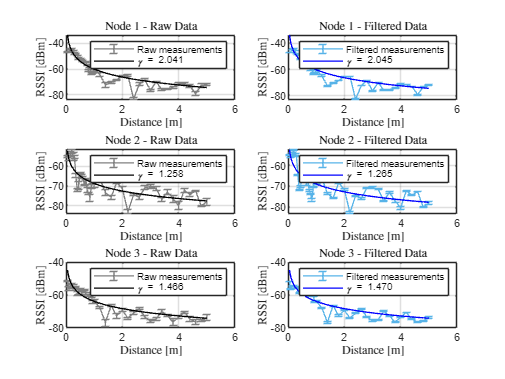

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                          RSSI PLOT                        %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear
clc
% Load and process data for each node
numNodes = 3;
numMeasurements = 50;
d = [0:0.05:1, 1.2:0.2:5];

% Pre-allocate arrays to store optimization results for each node
gamma_opt_raw_arr = zeros(numNodes, 1);
gamma_opt_filt_arr = zeros(numNodes, 1);
opt_RSSI_raw_arr = zeros(length(d) - 1, numNodes);
opt_RSSI_filt_arr = zeros(length(d) - 1, numNodes);

% Initialize structures to store error statistics
rawErrorStatsArr = repmat(struct('mean', [], 'std', [], 'range', [], 'min', [], 'max', [], 'quartiles', [], 'iqr', []), numNodes, 1);
filtErrorStatsArr = repmat(struct('mean', [], 'std', [], 'range', [], 'min', [], 'max', [], 'quartiles', [], 'iqr', []), numNodes, 1);

figure; % Create a new figure for subplots

for i = 1:numNodes
    filename = sprintf('RSSI_tp_node_%d.txt', i);
    [gamma_opt_raw, opt_RSSI_raw, raw_means, raw_CI, gamma_opt_filt, opt_RSSI_filt, filt_means, filt_CI, rawErrorStats, filtErrorStats] = processNodeData(filename, d, numMeasurements);

    % Store results for later use if needed
    gamma_opt_raw_arr(i) = gamma_opt_raw;
    gamma_opt_filt_arr(i) = gamma_opt_filt;
    opt_RSSI_raw_arr(:, i) = opt_RSSI_raw;
    opt_RSSI_filt_arr(:, i) = opt_RSSI_filt;

    % Store the error statistics
    rawErrorStatsArr(i) = rawErrorStats;
    filtErrorStatsArr(i) = filtErrorStats;

    d_opt = d(2:end);

    % Plot colours
    Orange = [0.90, 0.62, 0];
    Sky_Blue = [0.34, 0.70, 0.91];
    Bluish_Green = [0, 0.62, 0.45];
    Blue = [0, 0.45, 0.70];
    Vermilion = [0.83, 0.37, 0];
    Reddish_Purple = [0.80, 0.47, 0.65];
    Yellow = [0.94, 0.89, 0.26];
    Gray = [0.5, 0.5, 0.5];

    % Plotting for each node
    subplot(3, 2, i*2-1);
    errorbar(d_opt, raw_means(2:end), raw_means(2:end)-raw_CI(2:end,1), raw_CI(2:end,2)-raw_means(2:end), 'Color', Gray, 'LineStyle', '-', 'CapSize', 6, 'LineWidth', 1);
    hold on;
    % Plot filtered data with confidence intervals
    plot(d_opt, opt_RSSI_raw, '-', 'LineWidth', 1, 'Color', 'k');
    xlabel('Distance [m]');
    ylabel('RSSI [dBm]');
    title(sprintf('Node %d - Raw Data', i), 'Interpreter', 'latex');
    legend('Raw measurements', sprintf('\\gamma = %.3f', gamma_opt_raw));
    grid on;
    hold off;

    subplot(3, 2, i*2);
    errorbar(d_opt, filt_means(2:end), filt_means(2:end)-filt_CI(2:end,1), filt_CI(2:end,2)-filt_means(2:end), 'Color', Sky_Blue, 'LineStyle','-', 'CapSize', 6, 'LineWidth', 1);
    hold on;
    % Plot theoretical curve
    plot(d_opt, opt_RSSI_filt, '-', 'LineWidth', 1, 'Color', 'b');
    xlabel('Distance [m]');
    ylabel('RSSI [dBm]');
    title(sprintf('Node %d - Filtered Data', i), 'Interpreter','latex');
    legend('Filtered measurements', sprintf('\\gamma = %.3f', gamma_opt_filt));
    grid on;
    hold off;
end


% % Set the figure size
% fig = gcf;
% fig.PaperUnits = 'centimeters';
% fig.PaperPosition = [0 0 20 27]; % This will stretch the plot across an width = 21cm, height = 29.7cm
% fig.PaperSize = [20 27];
% 
% % Save the figure with the specified resolution
% print(fig, 'RSSI_Distance_Plots', '-depsc', '-r600'); % '-depsc' is used for EPS color

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                          CDF PLOT                         %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear
clc
% Load and process data for each node
numNodes = 3;
numMeasurements = 50;
d = [0:0.05:1, 1.2:0.2:5];

% Pre-allocate arrays to store optimization results for each node
gamma_opt_raw_arr = zeros(numNodes, 1);
gamma_opt_filt_arr = zeros(numNodes, 1);
opt_RSSI_raw_arr = zeros(length(d) - 1, numNodes);
opt_RSSI_filt_arr = zeros(length(d) - 1, numNodes);

% Initialize structures to store error statistics
rawErrorStatsArr = repmat(struct('mean', [], 'std', [], 'range', [], 'min', [], 'max', [], 'quartiles', [], 'iqr', []), numNodes, 1);
filtErrorStatsArr = repmat(struct('mean', [], 'std', [], 'range', [], 'min', [], 'max', [], 'quartiles', [], 'iqr', []), numNodes, 1);
raw_abs_errors_arr = zeros(length(d) - 1, numNodes);
filt_abs_errors_arr = zeros(length(d) - 1, numNodes);

figure; % Create a new figure for subplots
hold on;

for i = 1:numNodes
    filename = sprintf('RSSI_tp_node_%d.txt', i);
    [gamma_opt_raw, opt_RSSI_raw, raw_means, raw_CI, gamma_opt_filt, opt_RSSI_filt, filt_means, filt_CI, rawErrorStats, filtErrorStats, raw_errors, filt_errors] = processNodeData(filename, d, numMeasurements);

    % Store results for later use if needed
    gamma_opt_raw_arr(i) = gamma_opt_raw;
    gamma_opt_filt_arr(i) = gamma_opt_filt;
    opt_RSSI_raw_arr(:, i) = opt_RSSI_raw;
    opt_RSSI_filt_arr(:, i) = opt_RSSI_filt;

    % Store the error statistics
    rawErrorStatsArr(i) = rawErrorStats;
    filtErrorStatsArr(i) = filtErrorStats;
    raw_abs_errors_arr = abs(raw_errors);
    filt_abs_errors_arr = abs(filt_errors);

    % Retrieve and display the error statistics for the current node
    fprintf('Node %d - Raw Error Statistics:\n', i);
    disp(rawErrorStatsArr(i));

    fprintf('Node %d - Filtered Error Statistics:\n', i);
    disp(filtErrorStatsArr(i));

    d_opt = d(2:end);

    % Plotting
    line_styles = {'-', '--', ':'};
    % Plot CDF using average k-values for each speed
    sorted_abs_errors_raw = sort(raw_abs_errors_arr);
    cdf_abs_errors_raw = (1:length(sorted_abs_errors_raw))' / length(sorted_abs_errors_raw);
    plot(sorted_abs_errors_raw, cdf_abs_errors_raw, 'Color', 'k', 'LineStyle', line_styles{i}, 'LineWidth', 1.5);
    
    % Plot CDF using mean k-value for comparison
    sorted_abs_errors_filt = sort(filt_abs_errors_arr);
    cdf_abs_errors_mean_k = (1:length(sorted_abs_errors_filt))' / length(sorted_abs_errors_filt);
    plot(sorted_abs_errors_filt, cdf_abs_errors_mean_k, 'Color', 'b', 'LineStyle', line_styles{i}, 'LineWidth', 1.5);
end

Node 1 - Raw Error Statistics:


         mean: -1.5815
          std: 4.3190
        range: 17.7814
          min: -15.2216
          max: 2.5598
    quartiles: [-3.7203 0.2489 1.5317 2.2292]
          iqr: 5.2520



Node 1 - Filtered Error Statistics:


         mean: -1.5645
          std: 4.2982
        range: 17.5426
          min: -14.9744
          max: 2.5683
    quartiles: [-3.7959 0.3552 1.6021 2.2338]
          iqr: 5.3981



Node 2 - Raw Error Statistics:


         mean: -0.1794
          std: 4.2005
        range: 17.2949
          min: -9.8909
          max: 7.4040
    quartiles: [-2.7367 0.1463 3.5618 4.5822]
          iqr: 6.2985



Node 2 - Filtered Error Statistics:


         mean: -0.1047
          std: 4.2114
        range: 17.0478
          min: -9.5342
          max: 7.5135
    quartiles: [-2.6395 0.2007 3.7000 4.6530]
          iqr: 6.3395



Node 3 - Raw Error Statistics:


         mean: -0.8697
          std: 3.2214
        range: 14.6953
          min: -10.6779
          max: 4.0174
    quartiles: [-2.7212 -0.4958 1.6939 2.5728]
          iqr: 4.4151



Node 3 - Filtered Error Statistics:


         mean: -0.9063
          std: 3.1817
        range: 14.5675
          min: -10.6264
          max: 3.9411
    quartiles: [-2.6938 -0.5305 1.6627 2.4547]
          iqr: 4.3565



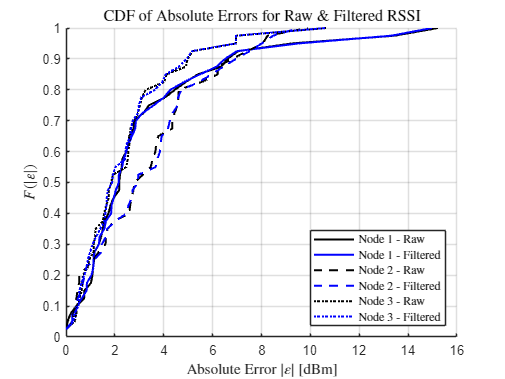


hold off;
xlabel('Absolute Error $|\varepsilon|$ [dBm]', 'Interpreter', 'latex');
ylabel('$F(|\varepsilon|)$', 'Interpreter', 'latex');
title('CDF of Absolute Errors for Raw \& Filtered RSSI', 'FontSize', 12, 'Interpreter', 'latex');
legend({'Node 1 - Raw', 'Node 1 - Filtered', 'Node 2 - Raw', 'Node 2 - Filtered', 'Node 3 - Raw', 'Node 3 - Filtered'}, 'Interpreter', 'latex', 'Location', 'southeast');
grid on;

% Set the figure size
fig = gcf;
fig.PaperUnits = 'centimeters';
fig.PaperPosition = [0 0 20 12]; % This will stretch the plot across an width = 21cm, height = 29.7cm
fig.PaperSize = [20 12];

% Save the figure with the specified resolution
print(fig, 'RSSI_Distance_CDF', '-depsc', '-r600'); % '-depsc' is used for EPS color

function [gamma_opt_raw, opt_rssi_raw, rawMeans, rawCI, gamma_opt_filt, opt_rssi_filt, filteredMeans, filteredCI, rawErrorStats, filtErrorStats, raw_errors, filt_errors] = processNodeData(filename, d, numMeasurements)
    % Load RSSI data from the file
    rssiData = dlmread(filename, '\t');

    % Extract raw and filtered measurements
    rawMeasurements = rssiData(1:2:end);
    filteredMeasurements = rssiData(2:2:end);

    % Initialize arrays for means and confidence intervals
    rawMeans = zeros(length(d), 1);
    filteredMeans = zeros(length(d), 1);
    rawCI = zeros(length(d), 2);
    filteredCI = zeros(length(d), 2);

    % Degrees of freedom for t-distribution
    dof = numMeasurements - 1;

    % t-value for 95% confidence interval
    t_value = tinv(0.975, dof);

    % Process data to calculate means and 95% confidence intervals
    for i = 1:length(d)
        % Raw data for current distance
        raw = rawMeasurements((i-1)*numMeasurements+1:i*numMeasurements);
        % Filtered data for current distance
        filtered = filteredMeasurements((i-1)*numMeasurements+1:i*numMeasurements);
        
        % Calculate means
        rawMeans(i) = mean(raw);
        filteredMeans(i) = mean(filtered);
        
        % Calculate standard errors
        rawSE = std(raw) / sqrt(numMeasurements);
        filteredSE = std(filtered) / sqrt(numMeasurements);
        
        % Calculate confidence intervals
        rawCI(i,:) = [rawMeans(i) - t_value * rawSE, rawMeans(i) + t_value * rawSE];
        filteredCI(i,:) = [filteredMeans(i) - t_value * filteredSE, filteredMeans(i) + t_value * filteredSE];
    end

    d0_idx = find(d == 1);

    rssi_d0_raw = rawMeans(d0_idx);
    rssi_d0_filt = filteredMeans(d0_idx);

    % Objective function to minimize
    obj_rssi_raw = @(gamma) sum((rssi_d0_raw - 10*gamma*log10(d(2:end)') - rawMeans(2:end)).^2);
    obj_rssi_filt = @(gamma) sum((rssi_d0_filt - 10*gamma*log10(d(2:end)') - filteredMeans(2:end)).^2);

    % Initial guess for gamma
    gamma_guess = 1.8;

    % Use fminsearch to find the best gamma
    options = optimset('MaxFunEvals', 1000, 'MaxIter', 1000);
    gamma_opt_raw = fminsearch(obj_rssi_raw, gamma_guess, options);
    gamma_opt_filt = fminsearch(obj_rssi_filt, gamma_guess, options);

    % Calculate the theoretical RSSI for all d, excluding the first element
    opt_rssi_raw = rssi_d0_raw - 10*gamma_opt_raw*log10(d(2:end));
    opt_rssi_filt = rssi_d0_filt - 10*gamma_opt_raw*log10(d(2:end));

    % Initialise array of errors
    raw_means_reduced = rawMeans(2:end);
    filt_means_reduced = filteredMeans(2:end);
    raw_errors = zeros(length(d) - 1, 1);
    filt_errors = zeros(length(d) - 1, 1);

    % Calculate absolute errors for raw and filtered data
    for i = 1:length(d)-1
        raw_errors(i) = raw_means_reduced(i) - opt_rssi_raw(i);
        filt_errors(i) = filt_means_reduced(i) - opt_rssi_filt(i);
    end

    % Statistics for absolute errors
    rawErrorStats.mean = mean(raw_errors);
    rawErrorStats.std = std(raw_errors);
    rawErrorStats.range = range(raw_errors);
    rawErrorStats.min = min(raw_errors);
    rawErrorStats.max = max(raw_errors);
    rawErrorStats.quartiles = quantile(raw_errors, [0.25 0.5 0.75 0.9]);
    rawErrorStats.iqr = iqr(raw_errors);

    filtErrorStats.mean = mean(filt_errors);
    filtErrorStats.std = std(filt_errors);
    filtErrorStats.range = range(filt_errors);
    filtErrorStats.min = min(filt_errors);
    filtErrorStats.max = max(filt_errors);
    filtErrorStats.quartiles = quantile(filt_errors, [0.25 0.5 0.75 0.9]);
    filtErrorStats.iqr = iqr(filt_errors);
    return
end